alp = 0.4;
SNR = 0:0.2:10;
SNR_n = 10.^(SNR/10);
BER_t = qfunc(sqrt(2*SNR_n));
BER = zeros(size(SNR));
sym_rate = 4.8e3;
k = 8;               % oversampling_factor
M = 4;               % M-PSK modulation
N = 2048;            % No. of symbols
EbNo = 2;            % Channel SNR

Ts = 1/sym_rate;     % Symbol period
T = Ts/k;            % Sampling period
t = -5*Ts : T : 5*Ts;
srrc = zeros(size(t));
for i = 1:1:length(t)
    if t(i) == 0
        srrc(i) = 1 - alp + (4 * alp / pi);
    elseif abs(t(i)) == Ts/(4*alp)
        srrc(i) = (alp/sqrt(2))*((1 + 2/pi)*sin(pi/(4*alp)) + (1 - 2/pi)*cos(pi/(4*alp)));
    else
        srrc(i) = (sin(pi*(1-alp)*t(i)/Ts) + (4*alp*t(i)/Ts)*cos(pi*(1+alp)*t(i)/Ts)) / ((pi*t(i)/Ts)*(1 - (4*alp*t(i)/Ts)^2));
    end
end

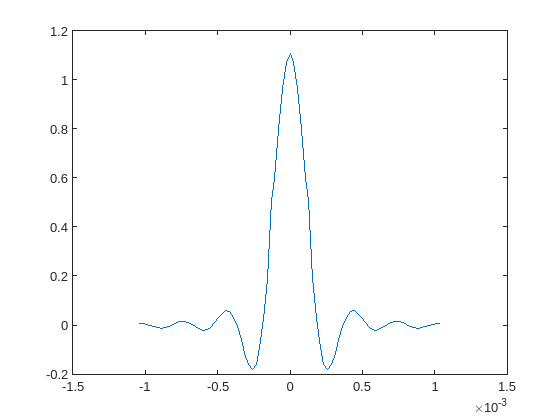

plot(t,srrc);

inp_signal = randi([0,3],N,1);
txSig = pskmod(inp_signal,M,pi/M);
%scatterplot(txSig);

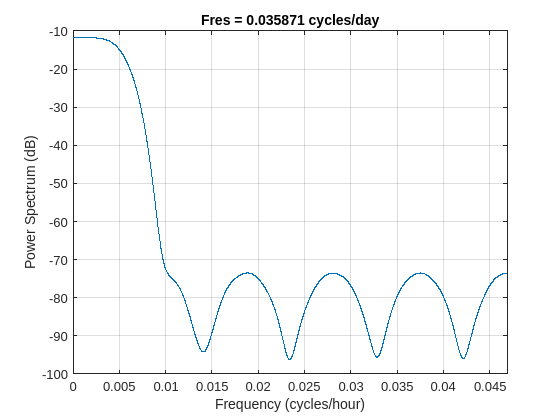

rc = conv(srrc,srrc);
rc = rc/max(rc);
pspectrum(rc,T);

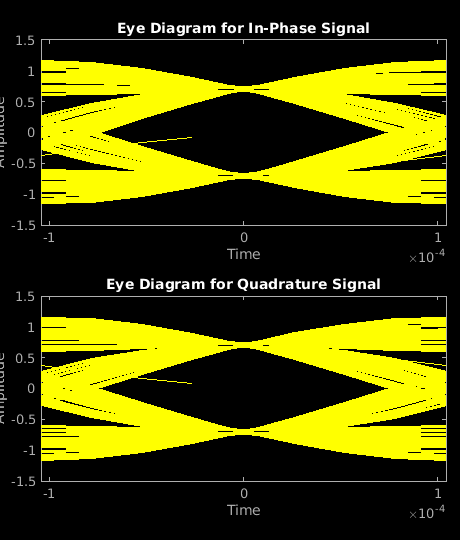

filt_inp = upsample(txSig,k); 
filt_out = conv(filt_inp, rc,'same');
rxSig = downsample(filt_out,8);
%scatterplot(rxSig);
eyediagram(filt_out,2*M,Ts)

%pspectrum(filt_out,T);
out_signal = pskdemod(rxSig,M,pi/M);
numError = sum(inp_signal ~= out_signal)

numError = 0

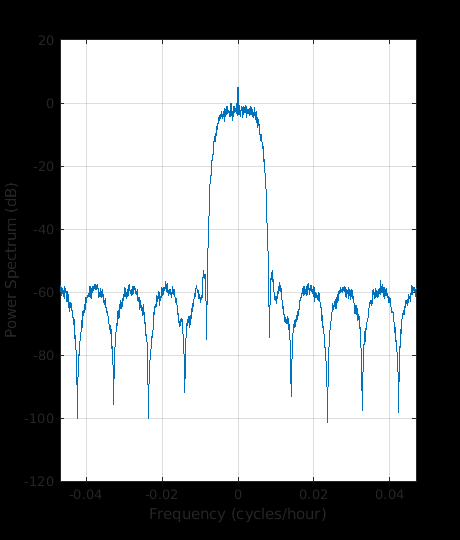

int_sig1 = conv(filt_inp,srrc,'same');
Ps = sum(abs(int_sig1).^2)/length(int_sig1);
noise = 0.3*rand(size(int_sig1),"like",1i);
Pn = sum(abs(noise).^2)/length(noise);
int_sig2 = int_sig1 + noise;
filt_out1 = conv(int_sig2,srrc,'same');
pspectrum(filt_out1,T)

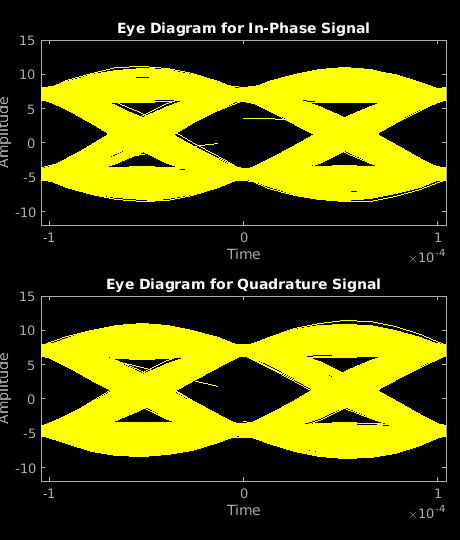

eyediagram(filt_out1,16,Ts)

rxSig1 = downsample(filt_out1,8);
%scatterplot(rxSig1);
out_signal1 = pskdemod(rxSig1,M,pi/M);
sum(inp_signal ~= out_signal1)

ans = 0